# Introduction to Classification of Partial Differential Equations (PDEs)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Partial Differential Equations (PDEs) are fundamental to the mathematical modeling of physical phenomena, appearing in fields as diverse as physics, engineering, and finance. They describe how heat, sound, fluid flow, and electromagnetic fields change over space and time. A PDE involves rates of change with respect to multiple variables. Unlike ordinary differential equations (ODEs), which involve derivatives with respect to a single variable, PDEs deal with functions of several variables and their partial derivatives. Engineers and scientists frequently encounter complex problems that can be modeled and solved using PDEs, and the first step in solving them is recognizing the features of the equations in question.

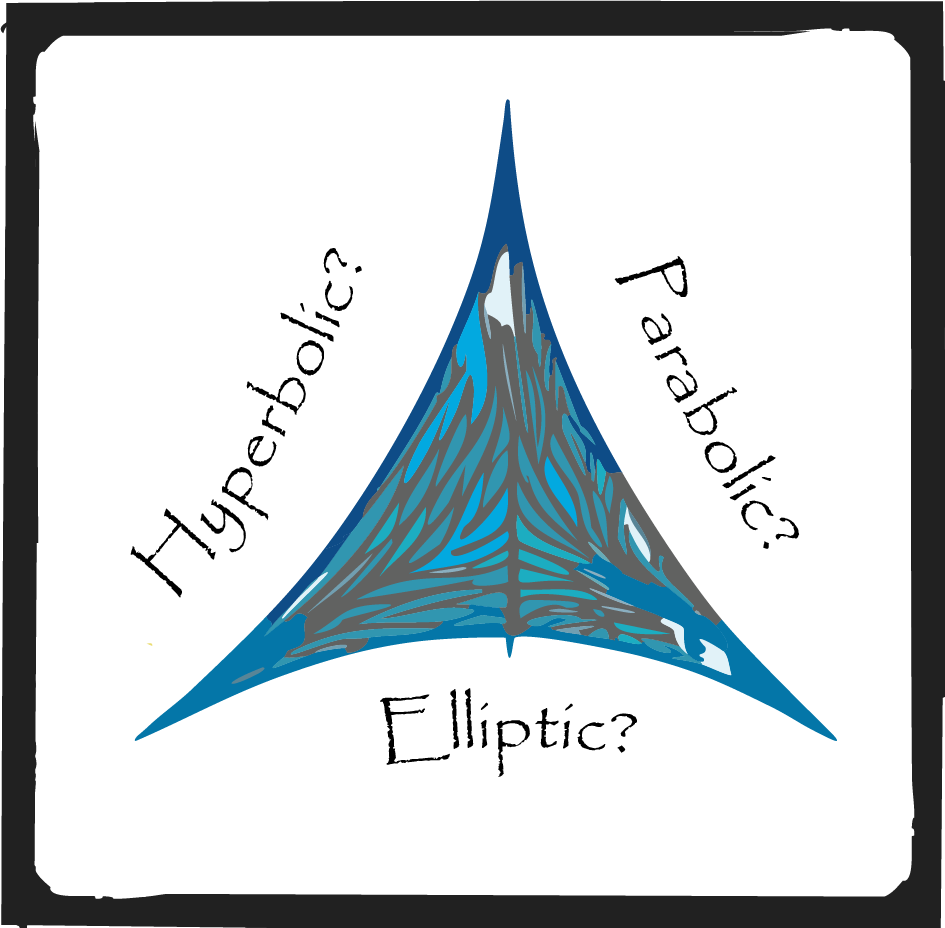

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free two-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Classification of PDEs

There are many aspects to consider when classifying a partial differential equation. 

**Order**: One classification involves the highest order derivatives; the result is a positive integer.

**Linearity**: Another classification considers the coefficients and divides PDEs into linear and nonlinear classes. Linear equations are much easier to solve.

**Homogeneity**: A third classification checks only the part of the equation that doesn't involve any dependent variables at all. If it is zero, we call the equation homogeneous, and if it is nonzero, the equation is nonhomogeneous. 

**Type:** This script will dive into classifying PDEs into elliptic, hyperbolic, and parabolic types. The classification of PDEs into types is not just an academic exercise but a practical tool that guides the selection of solution methods and informs the expected behavior of the system under study. 

## The General Second-Order Linear PDE

Consider a general second-order linear PDE in two variables $x$ and $y$:


$${A(x,y) \frac{\partial^2 u}{\partial x^2} + B(x,y) \frac{\partial^2 u}{\partial x \partial y} + C(x,y) \frac{\partial^2 u}{\partial y^2} + D(x,y) \frac{\partial u}{\partial x} + E(x,y) \frac{\partial u}{\partial y} + F(x,y) u = G(x,y)}$$


where $A$, $B$, $C$, $D$, $E$, $F$, and $G$ are functions of $x$ and $y$, and $u = u(x,y)$ is the unknown function to be solved for. If $G(x,y)=0$ this equation is homogeneous.

### Classification Criteria

The classification for a second-order PDE depends on the discriminant $\Delta = B^2 - 4AC$:

- **Elliptic PDEs**: $\Delta < 0$. An example is the Laplace equation, $\frac{\partial^2u}{\partial x^2} + \frac{\partial^2u}{\partial y^2} = 0$ or $\nabla^2u=0$, in two dimensions. Elliptic PDEs are frequently assumed to be time-invariant and, therefore, used for steady-state analysis.

- **Hyperbolic PDEs**: $\Delta > 0$. An example is the one-dimensional wave equation, $\frac{\partial^2 u}{\partial t^2} - c^2 \frac{\partial^2 u}{\partial x^2} = 0$, but all hyperbolic PDEs have wave-like solutions where disturbances will propagate over time.

- **Parabolic PDEs**: $\Delta = 0$. An example is the one-dimensional heat equation, $\frac{\partial u}{\partial t} - \alpha \frac{\partial^2 u}{\partial x^2} = 0$. Parabolic equations are diffusive models where the solutions usually are smoothed out over positive time. 

### Elliptic PDEs: Structural Analysis and Electrostatics

**Steady-state analysis:** In any diffusive model, $\frac{\partial u}{\partial t} - \alpha\left(\frac{\partial^2 u}{\partial x^2}+\frac{\partial^2u}{\partial y^2}\right) = f(x,y)$, the steady-state analysis in the region where $\frac{\partial u}{\partial t}=0$ so transient behavior has damped out will reduce to a Poisson equation $\frac{\partial^2 u}{\partial x^2}+\frac{\partial^2u}{\partial y^2} = -\frac{1}{\alpha}f(x,y)$. 

**Electrostatics**: Elliptic PDEs such as Maxwell's equations model electrostatic potentials in electrical engineering. The Laplace equation governs the electric potential distribution in a region without charges. This is essential for designing capacitors and understanding the behavior of insulating materials.

### Hyperbolic PDEs: Signal Propagation and Fluid Dynamics

**Signal Propagation**: In telecommunications engineering, the wave equation (in its simplest form $\frac{\partial^2 u}{\partial t^2} - c^2 \nabla^2u = 0$) models the propagation of electromagnetic waves through various media. This is fundamental for designing antennas, understanding signal loss, and optimizing communication systems for clarity and range. Acoustic wave propagation applies to many fields, including acoustics, seismology, underwater communication, and ultrasound. 

**Fluid Dynamics**: Hyperbolic PDEs also appear in fluid dynamics, modeling the flow of gases and liquids under certain conditions. They help predict shock waves and can be used to design more efficient aircraft and understand supersonic flow. One non-linear example is the Navier-Stokes equation:


$$\rho \left( \frac{\partial \mathbf{u}}{\partial t} + \mathbf{u} \cdot \nabla \mathbf{u} \right) = -\nabla p + \mu \nabla^2 \mathbf{u} + \mathbf{f}$$


where:

- $\rho$ is the fluid density,

- $\mathbf{u}$ is the velocity vector field,

- $t$ is time,

- $p$ is the pressure,

- $\mu$ is the dynamic viscosity,

- $\nabla$ denotes the gradient operator, e.g. $\frac{\partial}{\partial x} + \frac{\partial}{\partial y}+ \frac{\partial}{\partial z}$

- $\nabla^2$ is the Laplacian operator, e.g. $\frac{\partial^2}{\partial x^2} + \frac{\partial^2}{\partial y^2}+ \frac{\partial^2}{\partial z^2}$

- $\mathbf{f}$ is a vector representing body forces (e.g., gravity).

### Parabolic PDEs: Heat Transfer and Diffusion Processes

**Heat Transfer**: The heat equation, $\frac{\partial u}{\partial t} - \alpha \nabla^2 u = 0$, where $\alpha = \frac{k}{c_p\rho}$ with $k$ = thermal conductivity, $c_p$ = specific heat capacity, and $\rho$= mass density, is extensively used in mechanical engineering for thermal analysis. It models the distribution and flow of heat in materials and is critical for designing heat exchangers, optimizing insulation, and ensuring the thermal safety of electronic devices.

**Diffusion Processes**: Parabolic PDEs model the diffusion of substances through media. This is important for many things, including understanding pollutant dispersion in the environment. 

## Practice Classifying a PDE

**Example: **

Consider the PDE:


$${3 \frac{\partial^2 u}{\partial x^2} - 2 \frac{\partial^2 u}{\partial x \partial y} + \frac{\partial^2 u}{\partial y^2} = 0}$$


Here, $A = 3$, $B = -2$, and $C = 1$. Thus, the discriminant $\Delta = (-2)^2 - 4(3)(1) = 4 - 12 = -8$.

Since $\Delta < 0$, this PDE is **elliptic**.

 **Exercise 1.**

Classify the PDE: 

coeffs1 = GenerateProblem(1);  

**Solution:**

eqnType = "unknown";
if ~exist("coeffs1","var")
    disp("You must generate a problem before you can solve it.")
else
    CheckExercise(eqnType,coeffs1)
end

 **Exercise 2.**

Classify the PDE: 

[coeffs2,f1,f2] = GenerateProblem(2);  

**Solution:**

eqnType = "unknown";
if ~exist("coeffs2","var")
    disp("You must generate a problem before you can solve it.")
else
    CheckExercise(eqnType,coeffs2,Flag1=f1,Flag2=f2)
end

**Reflect**

- Why is classifying PDEs into elliptic, hyperbolic, and parabolic types important for solving them?

- How does the discriminant $\Delta = B^2 - 4AC$ help determine the nature of a second-order PDE?

- Can you think of real-world phenomena that could be modeled by each type of PDE (elliptic, hyperbolic, and parabolic)?

## Integrating PDEs into Engineering Solutions

Engineers use numerical methods and computational tools, often implemented in MATLAB, to solve PDEs and apply these solutions to real-world problems. Understanding the nature of the PDE (elliptic, hyperbolic, or parabolic) helps in selecting the appropriate numerical method, such as finite difference methods, finite element methods, or spectral methods, and in interpreting the results within the context of the physical problem.

Classifying PDEs into elliptic, hyperbolic, and parabolic types is a robust framework engineers leverage to model, analyze, and solve complex problems across various engineering domains. This understanding not only aids in the theoretical analysis but also in the practical application of solutions to improve technology and infrastructure in our societies.

## Further Practice

Learn to solve first-order wave equations in [`MethodOfCharacteristics.mlx`](matlab:open('./MethodOfCharacteristics.mlx')).

Build numerical solutions to the heat equation in [`FiniteDifference.mlx`](matlab:open('./Scripts/FiniteDifference.mlx')).

Explore a range of applications using the finite element model: [Documentation Examples](https://www.mathworks.com/help/pde/examples.html?category=finite-element-analysis-model&exampleproduct=all)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function [coeffs,var1,var2] = GenerateProblem(flag)
vals = randi(25,[4 1])-13;
coeffs = [vals(1:3); zeros([4 1])];
idx = randi(4)+3;
coeffs(idx) = vals(end);
var1 = 0;
var2 = 0;

syms t x u(t,x)
if flag == 2
    var1 = randi(5);
    var2 = randi(7);
end
[A,B,C,D,E,F,G] = ModifyCoefficients(coeffs,Flag1=var1,Flag2=var2);

MyEqn = simplify(A*diff(u,t,t) + B*diff(u,x)*diff(u,t)+C*diff(u,x,x)+ D*diff(u,t)+E*diff(u,x)+F*u == G);
displayFormula("MyEqn")
end

function CheckExercise(soln,coeffs,opts)
arguments
    soln
    coeffs
    opts.Flag1 = 0
    opts.Flag2 = 0
end

if soln == "unknown" && opts.Flag1 == 0 && opts.Flag2 == 0
    disp("This is the default. Please select a classification.")
    return
end
syms t x
[A,B,C] = ModifyCoefficients(coeffs,Flag1=opts.Flag1,Flag2=opts.Flag2);
if mod(opts.Flag1,2)==0
    MyVar = x;
else
    MyVar = t;
end
D = B^2-4*A*C;
flag = false;
if isAlways(D > 0,"Unknown","false")
    if soln == "hyperbolic"
        flag = true;
        str = "greater than";
    end
elseif isAlways(D < 0,"Unknown","false")
    if soln == "elliptic"
        flag = true;
        str = "less than";
    end
elseif isAlways(D==0,"Unknown","false")
    if soln == "parabolic"
        flag = true;
        str = "equal to";
    end
else
    if soln == "varies"
        flag = true;
        str = "changing with respect to";
    end
end
if flag && soln ~= "varies"
    disp("This is correct. The discriminant is ")
    displayFormula("Delta = D")
    disp("which is "+str+" 0.")
elseif flag && soln == "varies"
    disp("This is correct. The discriminant is ")
    displayFormula("Delta = D")
    [Dgt0,Pargt0,Condgt0] = solve(D>0,MyVar,ReturnConditions=true);
    Deq0 = solve(D==0,MyVar);
    [Dlt0,Parlt0,Conlt0] = solve(D<0,MyVar,ReturnConditions=true);
    displayFormula(['"This is hyperbolic when "' "Delta > 0" '", that is when "' "MyVar=Dgt0" '" and "' "Condgt0"])
    displayFormula(['"This is parabolic when "' "Delta == 0" '", that is when "' "MyVar=Deq0"])
    displayFormula(['"This is elliptic when "' "Delta < 0" '", that is when "' "MyVar=Dlt0" '" and "' "Conlt0"])
else
    disp("This is incorrect. What is the discriminant?")
end

end

function [A,B,C,D,E,F,G] = ModifyCoefficients(coeffs,opts)
arguments
    coeffs
    opts.Flag1 = 0;
    opts.Flag2 = 0;
end
syms t x
A = coeffs(1);
B = coeffs(2);
C = coeffs(3);
D = coeffs(4);
E = coeffs(5);
F = coeffs(6);
G = coeffs(7);
switch opts.Flag1
    case 1
        MyVar = t;
    case 2
        MyVar = x;
    case 3
        MyVar = sin(t);
    case 4
        MyVar = x^2;
    case 5
        MyVar = (x-3*t);
    otherwise

end

switch opts.Flag2
    case 1
        A = A*MyVar;
    case 2
        B = B*MyVar;
    case 3
        C = C*MyVar;
    case 4
        D = D*MyVar;
    case 5
        E = E*MyVar;
    case 6
        F = F*MyVar;
    case 7
        G = G*MyVar;
    otherwise
end
end